## **Digital Image Processing Assignment 2**

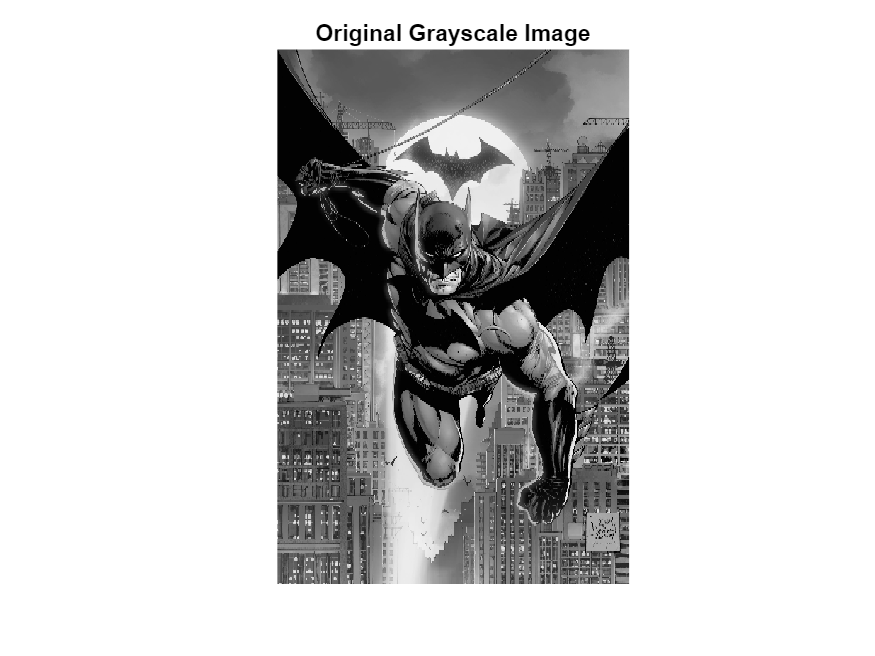

%% Digital Image Processing Assignment 2
% **Name:** Naga Prem Sai Nellure
% **Email:** nnellure2022@fau.edu
% **Professor:** Dr. Velibor Adzic

%% Question 1: Binary Mask and Filtering
% *Description:* 
% This section creates a binary mask for the region of interest and applies Gaussian, 
% Average, Laplacian, and Prewitt filters to the image.
% 
% *Code:*
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

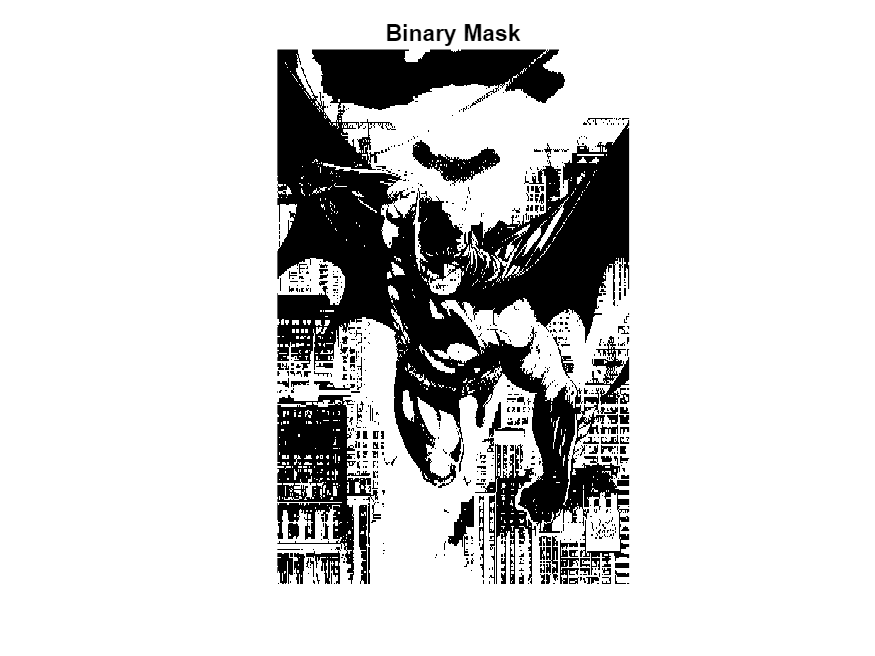

threshold_value = 100;
binary_mask = imbinarize(gray_img, threshold_value/255);
figure, imshow(binary_mask);
title('Binary Mask');

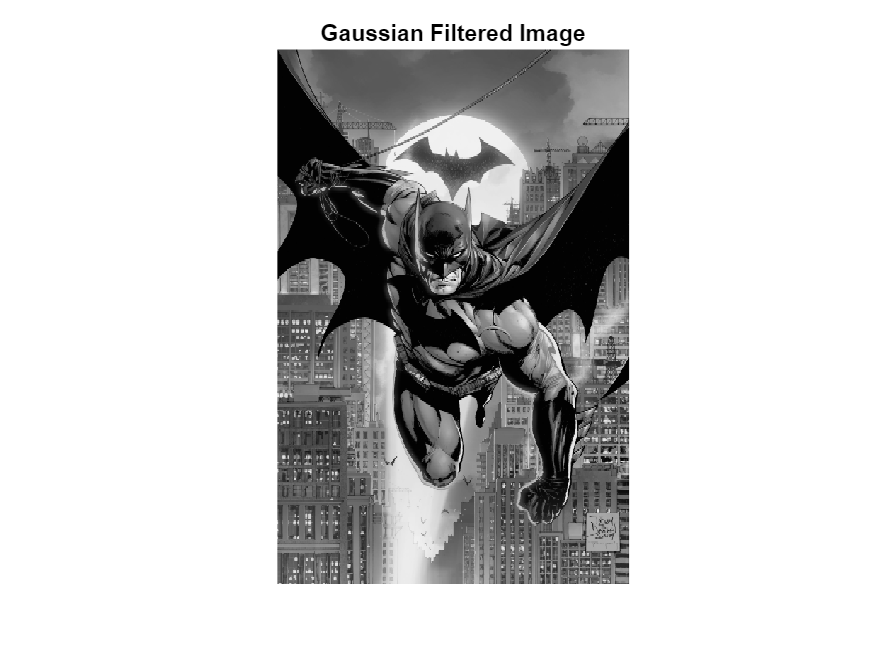

h_gaussian = fspecial('gaussian', [5,5], 2);
img_gaussian = imfilter(gray_img, h_gaussian);
figure, imshow(img_gaussian);
title('Gaussian Filtered Image');

disp('Histogram for Gaussian Filtered Image:');

Histogram for Gaussian Filtered Image:


disp(histcounts(img_gaussian));

       10853     1011795       51296       26301       17938       15555       14948       13242       11039       11248       10076       10237       10228        8234        7990        8503        8284        8212        7519        7356        8456        9017        8251        7462        7284        7268        7065        6950        6740        6824        7160        7345        7588        7824        7899        7793        7883        8287        9204        9701        9935        9874       10169       10025       10117       10110       10240       10431       10494       10942       11451       11835       11594       12006       12597       12964       13425       14215       14349       15134       16153       16236       17800       18092       19580       19969       24920       27861       27280       24157       25098       24347       25937       26355       27629       25945       26278       26647       28624       33801       31877       34295       35276    

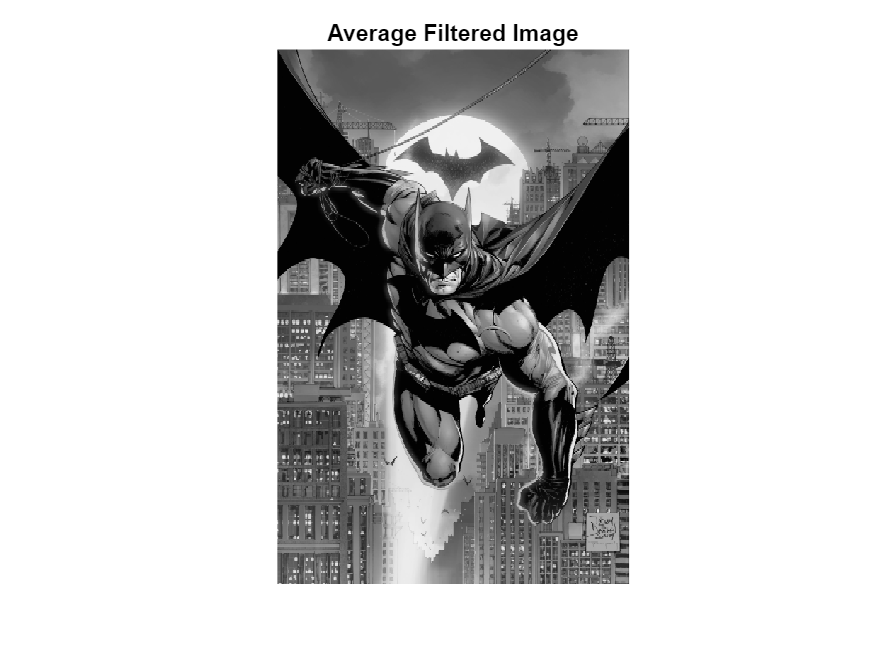

h_average = fspecial('average', [5,5]);
img_avg = imfilter(gray_img, h_average);
figure, imshow(img_avg);
title('Average Filtered Image');

disp('Histogram for Average Filtered Image:');

Histogram for Average Filtered Image:


disp(histcounts(img_avg));

        9519     1008839       50084       26133       17822       15484       14868       12960       10853       11203        9917       10318        9993        8410        8069        8528        8226        8168        7714        7483        8566        8917        8186        7570        7360        7360        7080        7021        7012        7006        7286        7290        7604        7911        7844        7859        8036        8404        9204        9851        9717        9807       10208       10033        9972        9977       10118       10423       10635       10859       11028       11406       11706       11964       12714       13008       13472       14185       14507       15363       16321       16212       17507       18031       19117       20225       24817       27629       26918       24266       24967       24658       25848       25719       27595       26450       26168       27018       29005       33893       32283       34140       35683    

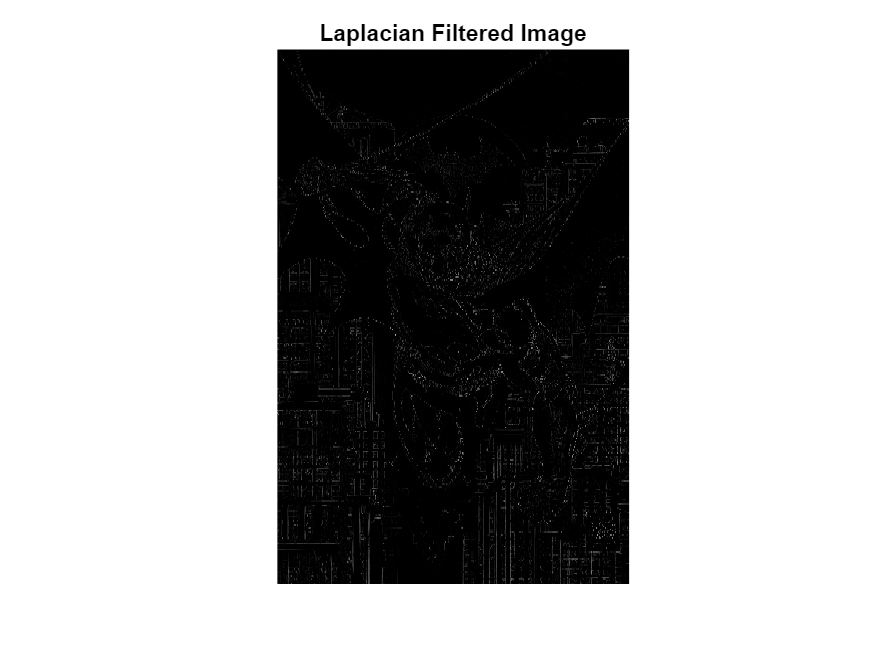

h_laplacian = fspecial('laplacian', 0.2);
img_laplacian = imfilter(gray_img, h_laplacian);
figure, imshow(img_laplacian, []);
title('Laplacian Filtered Image');

disp('Histogram for Laplacian Filtered Image:');

Histogram for Laplacian Filtered Image:


disp(histcounts(img_laplacian));

     4032366           0           0           0           0      456887           0           0           0           0      252209           0           0           0           0      138648           0           0           0           0      102998           0           0           0           0       84208           0           0           0           0       70424           0           0           0           0       59367           0           0           0           0       51637           0           0           0           0       44806           0           0           0           0       39828           0           0           0           0       35387           0           0           0           0       32423           0           0           0           0       29437           0           0           0           0       27794           0           0           0           0       25444           0           0           0           0       23522           0           0    

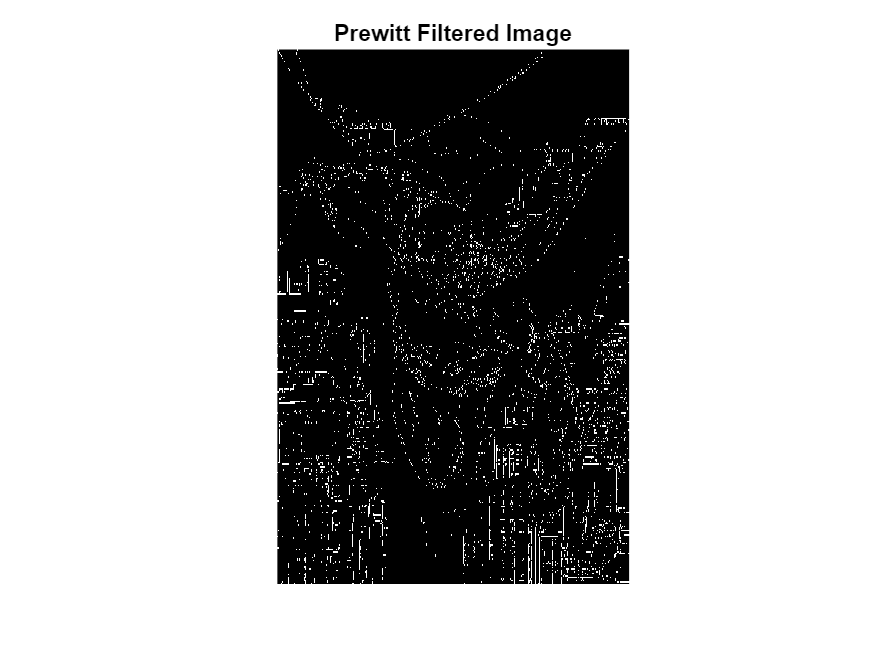

img_prewitt = edge(gray_img, 'prewitt');
figure, imshow(img_prewitt);
title('Prewitt Filtered Image');

disp('Histogram for Prewitt Filtered Image:');

Histogram for Prewitt Filtered Image:


disp(histcounts(img_prewitt));

     5766828      234944




%Explanation
disp('Explanation and Observations:');

Explanation and Observations:


disp('1. The original image is converted to grayscale to simplify the analysis.');

1. The original image is converted to grayscale to simplify the analysis.


disp('2. A binary mask is created using a threshold to isolate regions of interest.');

2. A binary mask is created using a threshold to isolate regions of interest.


disp('3. Gaussian and Average filters are applied to reduce noise and smooth the image.');

3. Gaussian and Average filters are applied to reduce noise and smooth the image.


disp('4. Laplacian and Prewitt filters are used to enhance and detect edges, respectively.');

4. Laplacian and Prewitt filters are used to enhance and detect edges, respectively.


disp('5. The effects of these filters are visualized and can be analyzed by comparing the output images and histograms.');

5. The effects of these filters are visualized and can be analyzed by comparing the output images and histograms.


disp('6. Histograms provide a quantitative view of the pixel intensity distribution after each filtering step, offering insights into the filter effects.');

6. Histograms provide a quantitative view of the pixel intensity distribution after each filtering step, offering insights into the filter effects.



%% Question 2: Floyd-Steinberg and Jarvis-Judice-Ninke Dithering
% *Description:*
% Floyd-Steinberg and Jarvis-Judice-Ninke dithering are applied to reduce the color depth of the image while maintaining visual quality.
% 
% *Code:*
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
gray_img = im2double(gray_img); 

floyd_steinberg = [0 0 7; 3 5 1] / 16;
jarvis_judice_ninke = [0 0 0 7 5; 3 5 7 5 3; 1 3 5 3 1] / 48;

floyd_img = ditheringAlgorithm(gray_img, floyd_steinberg);
jarvis_img = ditheringAlgorithm(gray_img, jarvis_judice_ninke);

figure, imshow(gray_img), title('Original Grayscale Image');

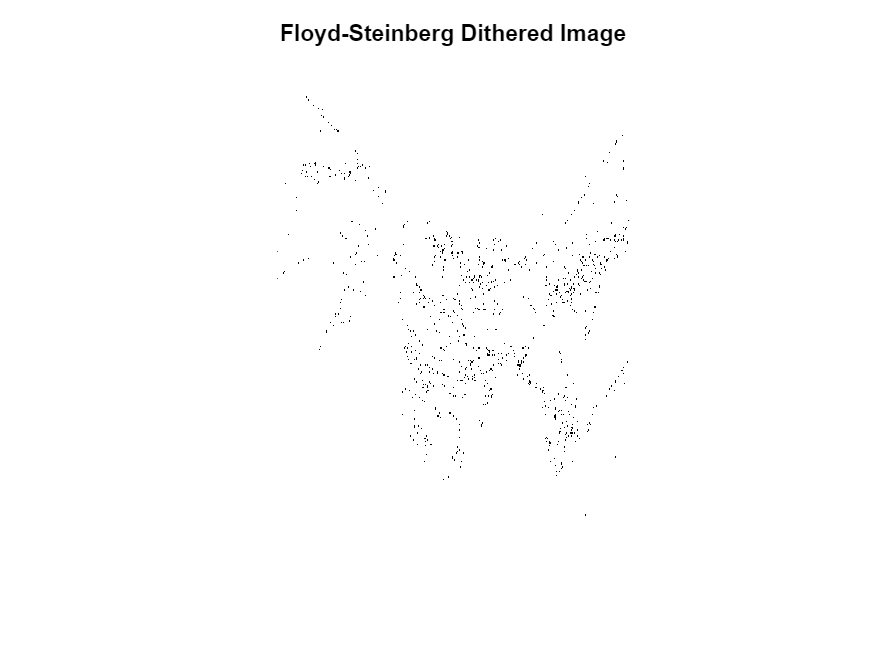

figure, imshow(floyd_img), title('Floyd-Steinberg Dithered Image');

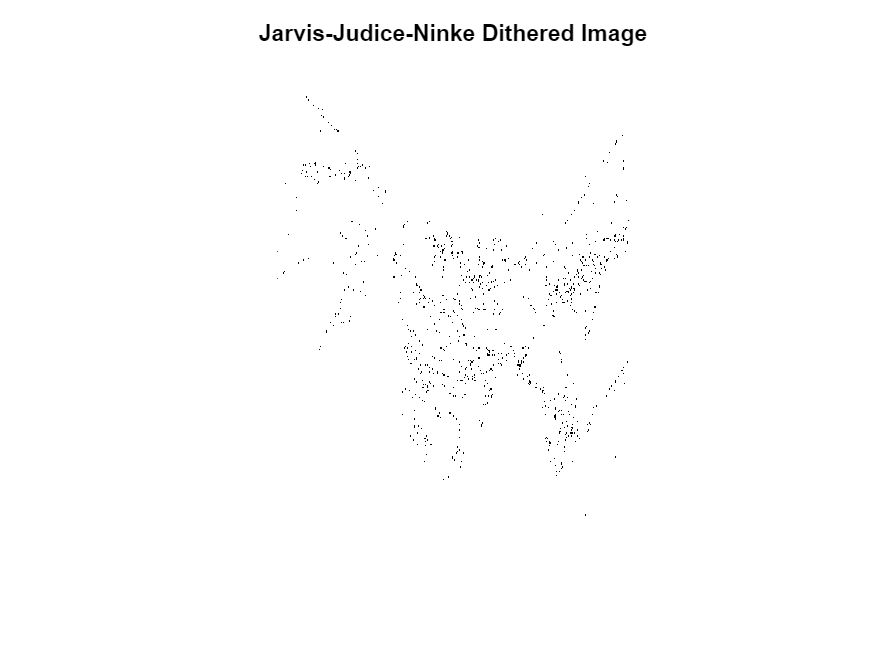

figure, imshow(jarvis_img), title('Jarvis-Judice-Ninke Dithered Image');

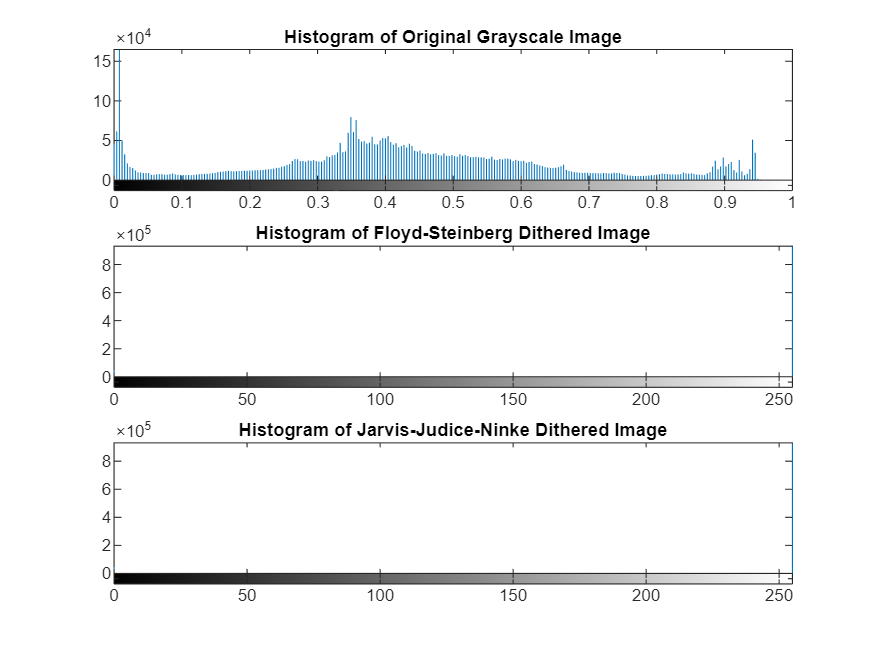

figure;
subplot(3,1,1), imhist(gray_img), title('Histogram of Original Grayscale Image');
subplot(3,1,2), imhist(floyd_img), title('Histogram of Floyd-Steinberg Dithered Image');
subplot(3,1,3), imhist(jarvis_img), title('Histogram of Jarvis-Judice-Ninke Dithered Image');


% Function to apply dithering based on input image and dither matrix
function output = ditheringAlgorithm(img, matrix)
    [rows, cols] = size(img);
    output = zeros(rows, cols); 
    for i = 1:rows
        for j = 1:cols
            old_pixel = img(i, j);
            new_pixel = round(255 * old_pixel);
            output(i, j) = new_pixel;
            error = old_pixel - new_pixel/255;
            [mat_rows, mat_cols] = size(matrix);
            for x = 1:mat_rows
                for y = 1:mat_cols
                    ix = i + x - 2;  
                    jy = j + y - 2 - floor(mat_cols/2);
                    if ix > 0 && ix <= rows && jy > 0 && jy <= cols
                        output(ix, jy) = output(ix, jy) + error * matrix(x, y);
                    end
                end
            end
        end
    end
    output = uint8(output * 255);  
end

% Explanation
disp('Explanation and Observations:');

Explanation and Observations:


disp('The Floyd-Steinberg dithering uses a 4-neighbor diffusion matrix and is primarily used for monochrome printers. The error is propagated to the neighboring pixels that are yet to be processed. This method is sensitive to the ordering of pixels.');

The Floyd-Steinberg dithering uses a 4-neighbor diffusion matrix and is primarily used for monochrome printers. The error is propagated to the neighboring pixels that are yet to be processed. This method is sensitive to the ordering of pixels.


disp('The Jarvis-Judice-Ninke dithering, on the other hand, uses a larger diffusion matrix with more neighbors, thus it tends to provide a smoother gradient in the dithered output at the cost of higher computational expense. It is effective for images with gradual tonal changes.');

The Jarvis-Judice-Ninke dithering, on the other hand, uses a larger diffusion matrix with more neighbors, thus it tends to provide a smoother gradient in the dithered output at the cost of higher computational expense. It is effective for images with gradual tonal changes.


disp('Both dithering techniques alter the image by distributing quantization errors across neighboring pixels, thereby reducing the appearance of quantization errors and improving the visual quality of the dithered images. The histograms demonstrate the redistribution of pixel intensities due to each method.');

Both dithering techniques alter the image by distributing quantization errors across neighboring pixels, thereby reducing the appearance of quantization errors and improving the visual quality of the dithered images. The histograms demonstrate the redistribution of pixel intensities due to each method.


disp('Numerical histogram values for both dithering techniques would further quantify the changes in pixel distribution and help in assessing the effectiveness of each dithering approach in different scenarios.');

Numerical histogram values for both dithering techniques would further quantify the changes in pixel distribution and help in assessing the effectiveness of each dithering approach in different scenarios.


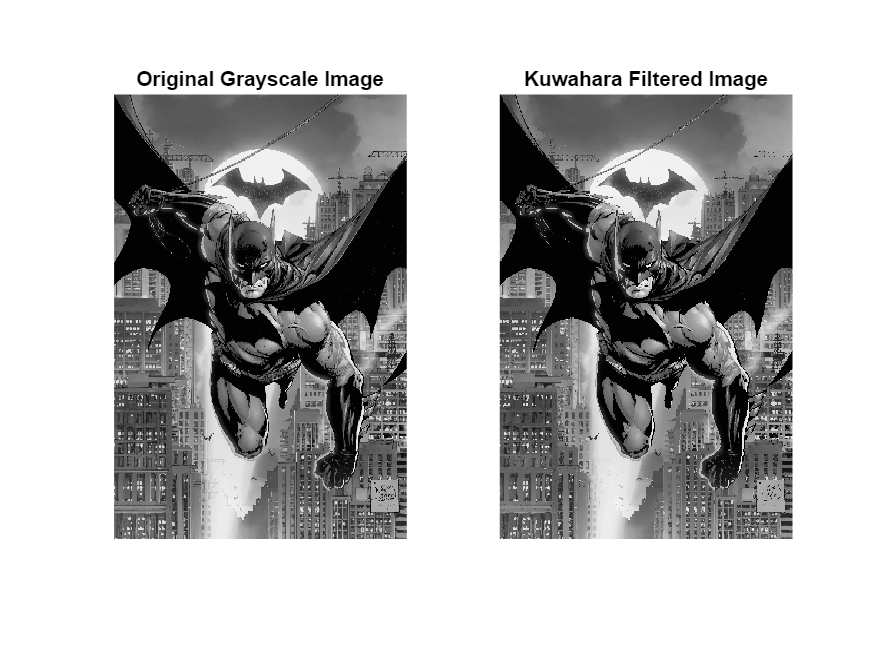


%% Question 3: Kuwahara Filter
% *Description:*
% The Kuwahara filter is applied with a 5x5 window to reduce noise while preserving edges.
% 
% *Code:*
function output = kuwaharaFilter(img, ksize)
    if mod(ksize, 2) == 0
        error('Kernel size must be odd.');
    end
    
    
    padSize = floor(ksize/2);
    paddedImg = padarray(img, [padSize padSize], 'replicate', 'both');
    
    [rows, cols] = size(img);
    output = zeros(rows, cols); 

    
    for i = 1:rows
        for j = 1:cols
            
            center_i = i + padSize;
            center_j = j + padSize;

            
            sub1 = paddedImg(center_i-padSize:center_i-1, center_j-padSize:center_j-1);
            sub2 = paddedImg(center_i-padSize:center_i-1, center_j+1:center_j+padSize);
            sub3 = paddedImg(center_i+1:center_i+padSize, center_j-padSize:center_j-1);
            sub4 = paddedImg(center_i+1:center_i+padSize, center_j+1:center_j+padSize);

            
            means = [mean(sub1(:)), mean(sub2(:)), mean(sub3(:)), mean(sub4(:))];
            vars = [var(double(sub1(:))), var(double(sub2(:))), var(double(sub3(:))), var(double(sub4(:)))];

            
            [~, idx] = min(vars);

            
            output(i, j) = means(idx);
        end
    end

    
    output = uint8(255 * mat2gray(output));
end




img = imread('Bat.jpg'); 
gray_img = rgb2gray(img);
filtered_img = kuwaharaFilter(gray_img, 5);
figure;
subplot(1,2,1), imshow(gray_img), title('Original Grayscale Image');
subplot(1,2,2), imshow(filtered_img), title('Kuwahara Filtered Image');

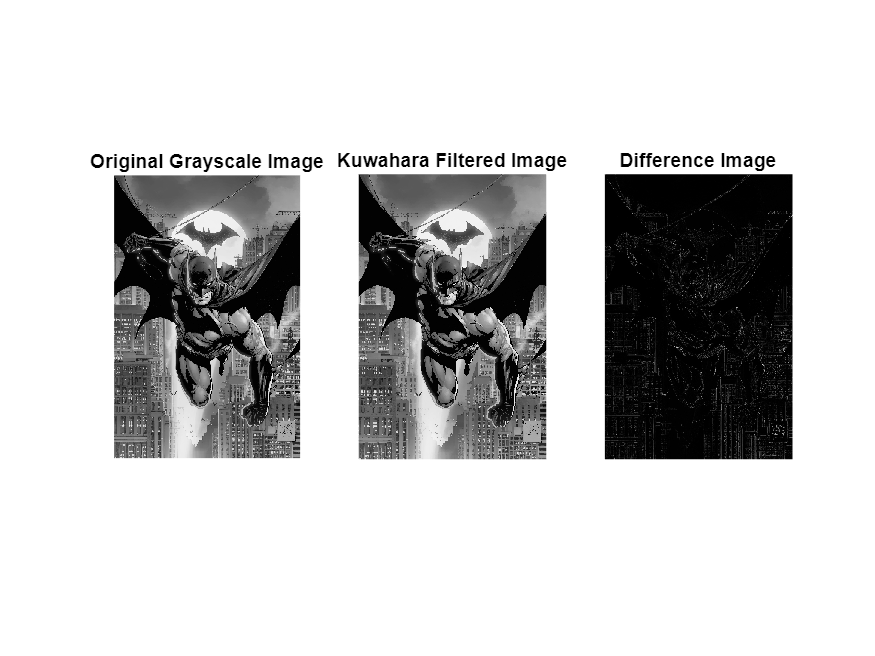

% Load the image one more time to check with the difference with kuwahara
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
filtered_img = kuwaharaFilter(gray_img, 5); 
figure;
subplot(1,3,1), imshow(gray_img), title('Original Grayscale Image');
subplot(1,3,2), imshow(filtered_img), title('Kuwahara Filtered Image');
diff_img = abs(double(gray_img) - double(filtered_img));
subplot(1,3,3), imshow(diff_img, []), title('Difference Image');

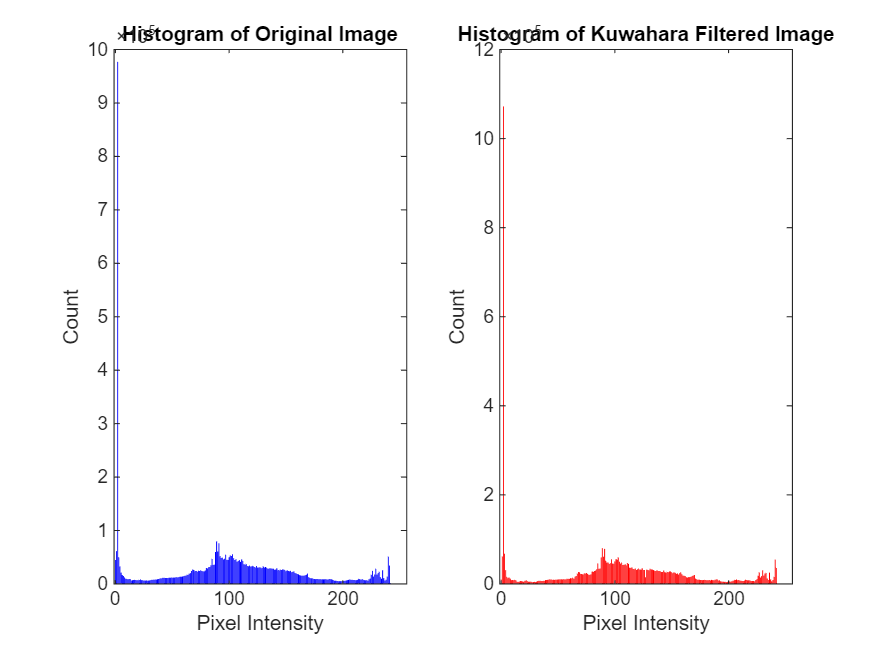

[hist_orig, orig_bins] = imhist(gray_img);
[hist_filt, filt_bins] = imhist(filtered_img);

figure;
subplot(1,2,1);
bar(orig_bins, hist_orig, 'b');
title('Histogram of Original Image');
xlabel('Pixel Intensity'); ylabel('Count');

subplot(1,2,2);
bar(filt_bins, hist_filt, 'r');
title('Histogram of Kuwahara Filtered Image');
xlabel('Pixel Intensity'); ylabel('Count');

disp('Histogram Values for Original Image:');

Histogram Values for Original Image:


disp([orig_bins, hist_orig]);

           0       45146
           1       61503
           2      976939
           3       50033
           4       32732
           5       21179
           6       16502
           7       15117
           8       12287
           9        9819
          10        9822
          11        8988
          12        9001
          13        9019
          14        6758
          15        6805
          16        7482
          17        7603
          18        7402
          19        6870
          20        6884
          21        7630
          22        8525
          23        7241
          24        6858
          25        6505
          26        6552
          27        6401
          28        6320
          29        6348
          30        6711
          31        7080
          32        7623
          33        7870
          34        7970
          35        8058
          36        8298
          37        8764
          38        9203
          39       10152


disp('Histogram Values for Kuwahara Filtered Image:');

Histogram Values for Kuwahara Filtered Image:


disp([filt_bins, hist_filt]);

           0        9691
           1       61515
           2     1072473
           3       67776
           4       30883
           5       16018
           6       13058
           7       14793
           8       11876
           9        8649
          10        9001
          11        8492
          12        9112
          13        8279
          14        4717
          15        4760
          16        5903
          17        6871
          18        6340
          19        5181
          20        5492
          21        6948
          22        8369
          23        6386
          24        5352
          25        4940
          26        4843
          27        4569
          28        3955
          29        4301
          30        4600
          31        5085
          32        6321
          33        6939
          34        6817
          35        6895
          36        6484
          37        6523
          38        7308
          39        8508



% Explanation
disp('Explanation of Kuwahara Filter Process and Observations:');

Explanation of Kuwahara Filter Process and Observations:


disp('The Kuwahara filter, applied here with a 5x5 window, is designed to preserve edge features while reducing noise in homogeneous areas.');

The Kuwahara filter, applied here with a 5x5 window, is designed to preserve edge features while reducing noise in homogeneous areas.


disp('This filter works by dividing the window into four overlapping sub-windows. Each sub-windows variance and mean are calculated.');

This filter works by dividing the window into four overlapping sub-windows. Each sub-windows variance and mean are calculated.


disp('The output pixel is set to the mean of the sub-window with the lowest variance, ensuring that edge details are preserved while smoothing areas without strong edges.');

The output pixel is set to the mean of the sub-window with the lowest variance, ensuring that edge details are preserved while smoothing areas without strong edges.


disp('This method is particularly effective in images with clear and smooth areas separated by sharp edges, making it ideal for images with significant texture variation.');

This method is particularly effective in images with clear and smooth areas separated by sharp edges, making it ideal for images with significant texture variation.


disp('The difference image highlights where the filter has made significant changes, typically around the edges and in regions with noise.');

The difference image highlights where the filter has made significant changes, typically around the edges and in regions with noise.


disp('Histogram comparisons provide a quantitative measure of the changes, showing how pixel intensities are distributed before and after filtering.');

Histogram comparisons provide a quantitative measure of the changes, showing how pixel intensities are distributed before and after filtering.


disp('Such visual and numerical analysis helps in understanding the filter’s impact on image aesthetics and quality.');

Such visual and numerical analysis helps in understanding the filter’s impact on image aesthetics and quality.


%% Question 4: Fourier Transform, Butterworth, and Gaussian Filters
% *Description:*
% Fourier Transform is applied to analyze the frequency domain of the image and two filters are implemented.
% 
% *Code:*
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

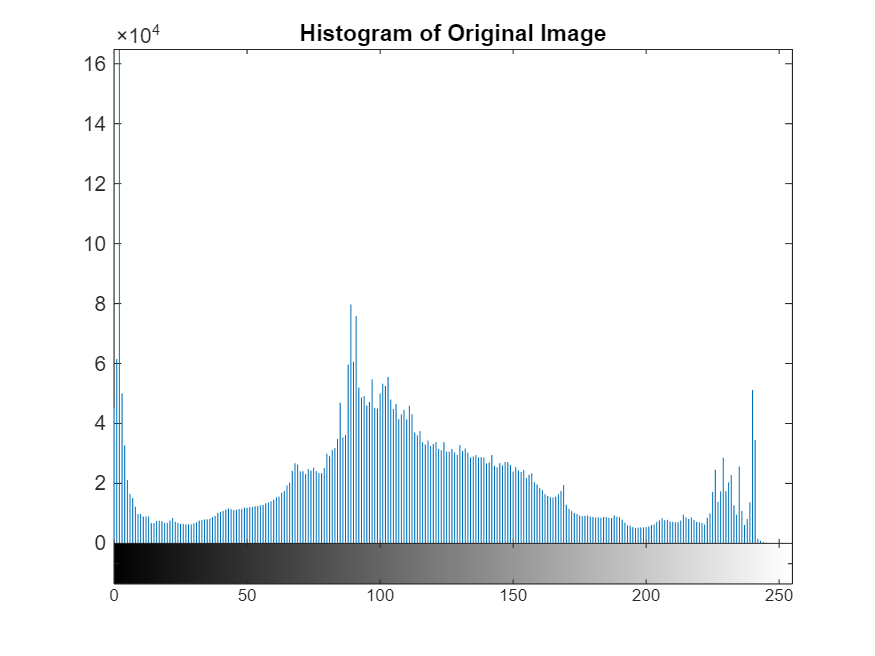

figure;
imhist(gray_img);
title('Histogram of Original Image');

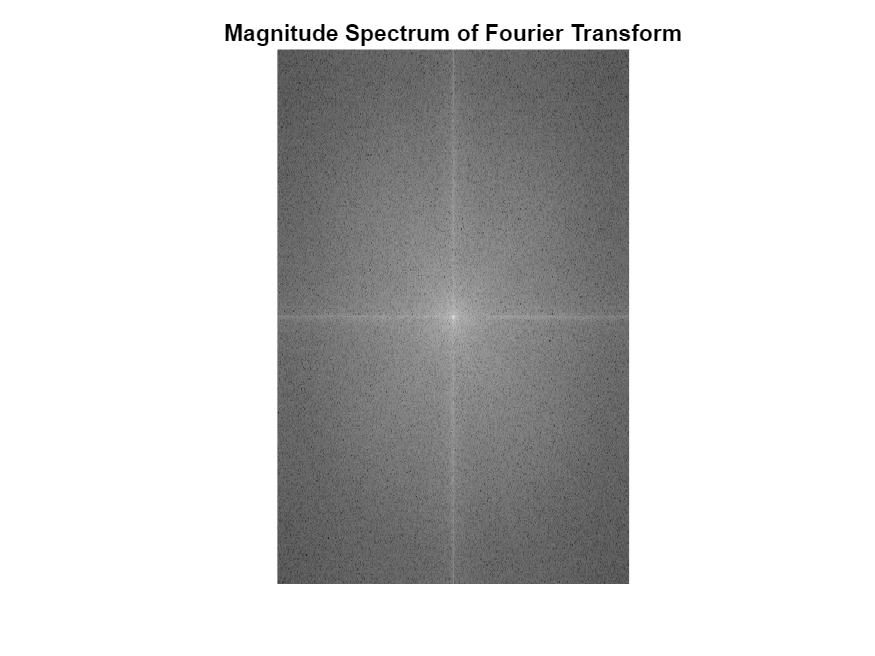

F = fft2(double(gray_img));
F_shifted = fftshift(F);
magnitude_spectrum = log(1+abs(F_shifted));
figure, imshow(magnitude_spectrum, []);
title('Magnitude Spectrum of Fourier Transform');

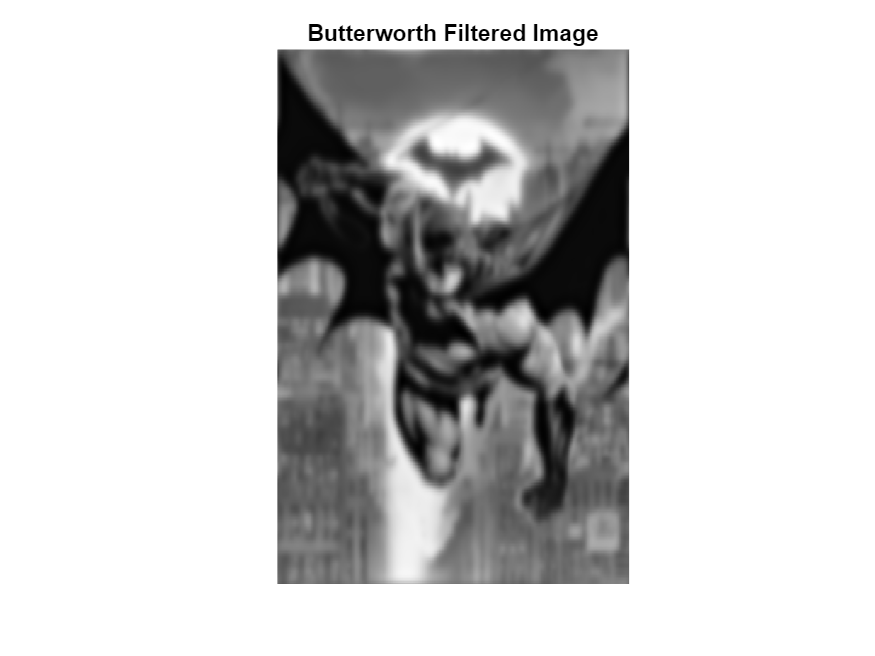

[u, v] = size(gray_img);
[U, V] = meshgrid(-v/2:v/2-1, -u/2:u/2-1);
D = sqrt(U.^2 + V.^2);
D0 = 25; 
n = 2; 
H = 1 ./ (1 + (D / D0).^(2*n)); 
G = H .* F_shifted;
G_shifted = ifftshift(G);
filtered_img_butter = real(ifft2(G_shifted));
figure, imshow(filtered_img_butter, []);
title('Butterworth Filtered Image');

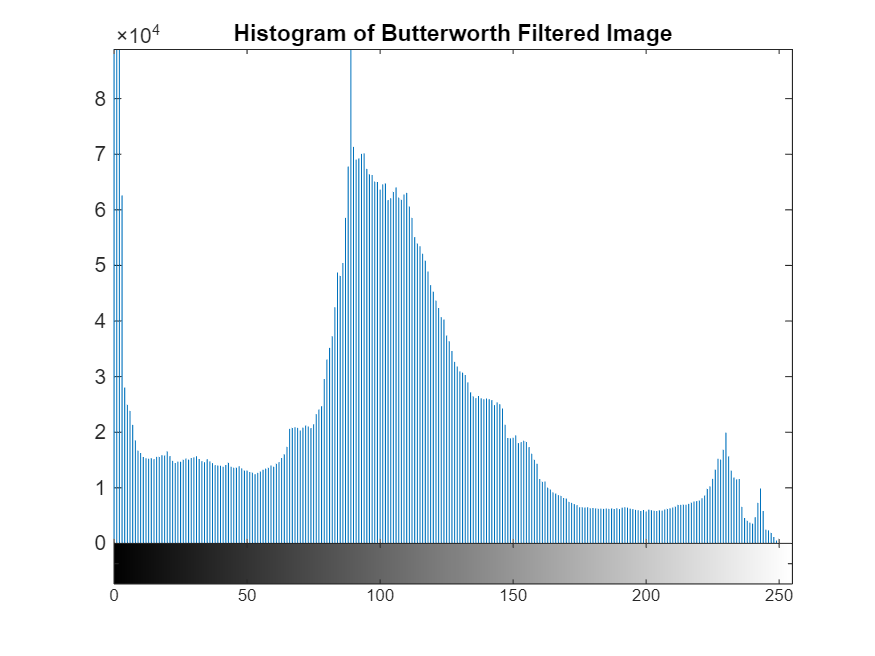

figure, imhist(uint8(filtered_img_butter));
title('Histogram of Butterworth Filtered Image');

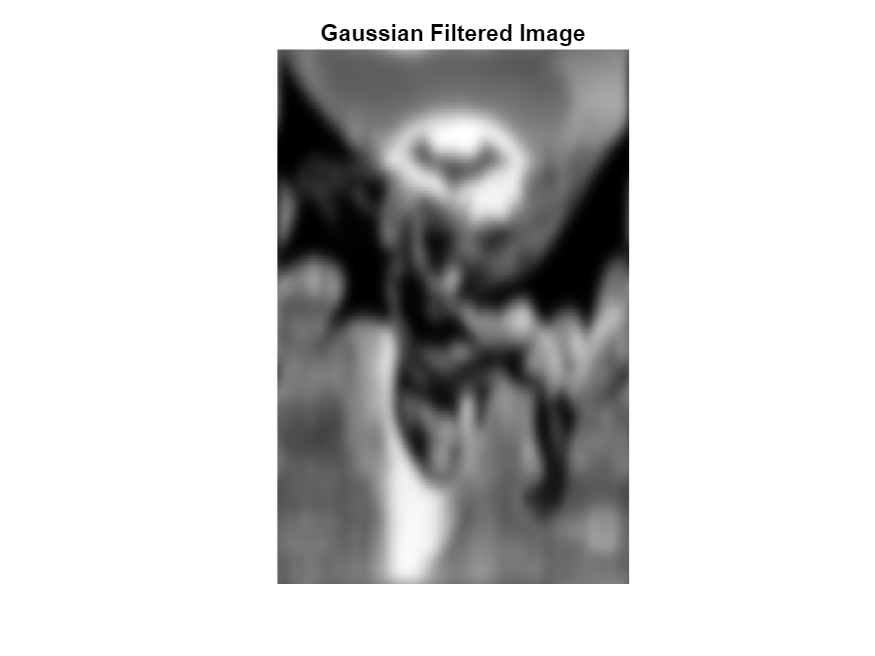

sigma = 10; 
H_gaussian = exp(-(D.^2) / (2*sigma^2));
G_gaussian = H_gaussian .* F_shifted;
G_gaussian_shifted = ifftshift(G_gaussian);
filtered_img_gaussian = real(ifft2(G_gaussian_shifted));
figure, imshow(filtered_img_gaussian, []);
title('Gaussian Filtered Image');

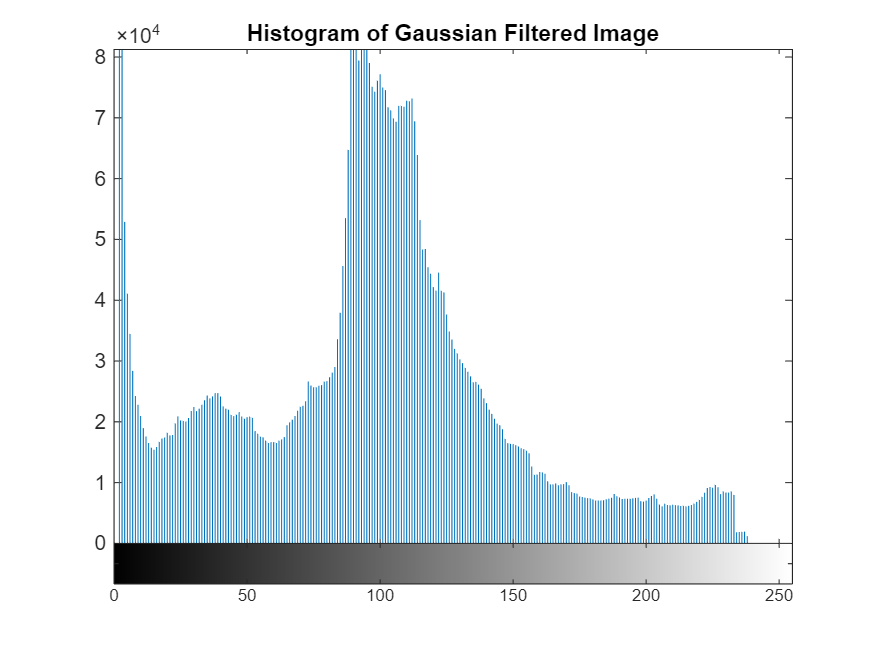

figure, imhist(uint8(filtered_img_gaussian));
title('Histogram of Gaussian Filtered Image');


mse_butter = immse(double(gray_img), double(filtered_img_butter));
psnr_butter = psnr(double(filtered_img_butter), double(gray_img));

mse_gaussian = immse(double(gray_img), double(filtered_img_gaussian));
psnr_gaussian = psnr(double(filtered_img_gaussian), double(gray_img));


fprintf('MSE for Butterworth Filtered Image: %f\n', mse_butter);

MSE for Butterworth Filtered Image: 821.065600


fprintf('PSNR for Butterworth Filtered Image: %f dB\n', psnr_butter);

PSNR for Butterworth Filtered Image: -29.143779 dB


fprintf('MSE for Gaussian Filtered Image: %f\n', mse_gaussian);

MSE for Gaussian Filtered Image: 1231.544830


fprintf('PSNR for Gaussian Filtered Image: %f dB\n', psnr_gaussian);

PSNR for Gaussian Filtered Image: -30.904502 dB



% Explanation
disp('Explanation of Fourier Transform, Butterworth, and Gaussian Filters:');

Explanation of Fourier Transform, Butterworth, and Gaussian Filters:


disp('Fourier Transform is used to analyze the frequency components of an image. The magnitude spectrum displays the intensity of the frequencies. Areas with high variations, such as edges, correspond to higher values in the spectrum.');

Fourier Transform is used to analyze the frequency components of an image. The magnitude spectrum displays the intensity of the frequencies. Areas with high variations, such as edges, correspond to higher values in the spectrum.


disp('Butterworth filter, a type of low-pass filter, is characterized by its smoothness and lack of ripples in the frequency magnitude response. This smoothness is due to the order of the filter and the cut-off frequency, which controls the transition from passband to stopband.');

Butterworth filter, a type of low-pass filter, is characterized by its smoothness and lack of ripples in the frequency magnitude response. This smoothness is due to the order of the filter and the cut-off frequency, which controls the transition from passband to stopband.


disp('Gaussian filter, also a low-pass filter, uses a Gaussian function for its impulse response. It is highly effective in reducing high-frequency components, thus smoothing the image. The standard deviation of the Gaussian function controls the extent of smoothing.');

Gaussian filter, also a low-pass filter, uses a Gaussian function for its impulse response. It is highly effective in reducing high-frequency components, thus smoothing the image. The standard deviation of the Gaussian function controls the extent of smoothing.


disp('The filters reduce noise and details, with the Butterworth filter providing a smoother transition compared to the sharper transition of the Gaussian filter.');

The filters reduce noise and details, with the Butterworth filter providing a smoother transition compared to the sharper transition of the Gaussian filter.


disp('Comparing the results, the Butterworth filter maintains more of the low-frequency components, while the Gaussian filter attenuates higher frequencies more aggressively.');

Comparing the results, the Butterworth filter maintains more of the low-frequency components, while the Gaussian filter attenuates higher frequencies more aggressively.


disp('Histograms and the MSE (Mean Squared Error) and PSNR (Peak Signal-to-Noise Ratio) metrics help quantify the effects of these filters on the image quality.');

Histograms and the MSE (Mean Squared Error) and PSNR (Peak Signal-to-Noise Ratio) metrics help quantify the effects of these filters on the image quality.



%% Question 5: Quantization to 32 Levels
% *Description:*
% This section performs quantization on the grayscale image to reduce it to 32 levels using `imresize`.
% 
% *Code:*
img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

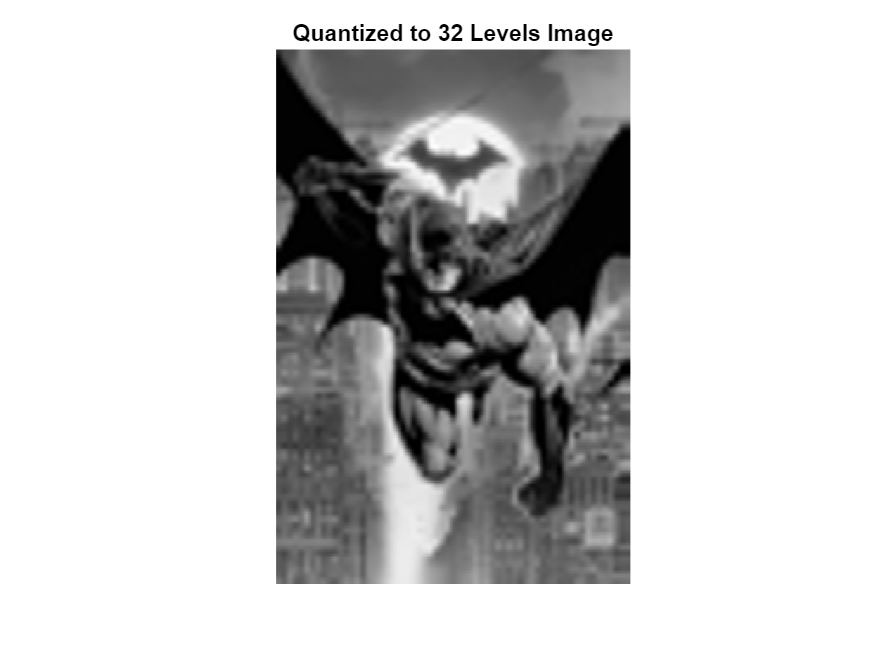

quantized_img = imresize(imresize(gray_img, 1/32), 32);
figure, imshow(quantized_img);
title('Quantized to 32 Levels Image');

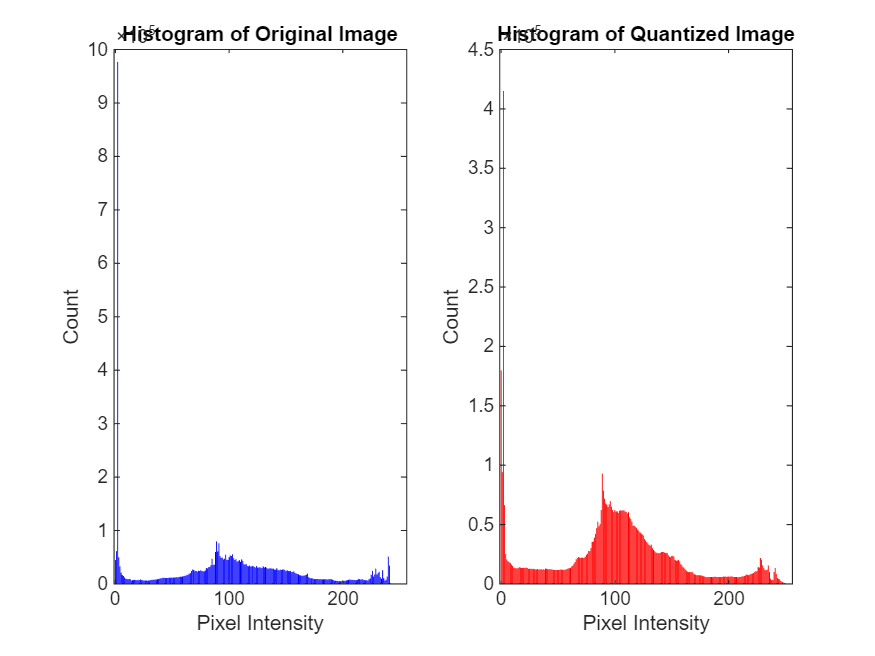

[hist_orig, orig_bins] = imhist(gray_img);
[hist_quant, quant_bins] = imhist(quantized_img);

figure;
subplot(1,2,1);
bar(orig_bins, hist_orig, 'b');
title('Histogram of Original Image');
xlabel('Pixel Intensity'); ylabel('Count');

subplot(1,2,2);
bar(quant_bins, hist_quant, 'r');
title('Histogram of Quantized Image');
xlabel('Pixel Intensity'); ylabel('Count');

disp('Histogram Values for Original Image:');

Histogram Values for Original Image:


disp([orig_bins, hist_orig]);

           0       45146
           1       61503
           2      976939
           3       50033
           4       32732
           5       21179
           6       16502
           7       15117
           8       12287
           9        9819
          10        9822
          11        8988
          12        9001
          13        9019
          14        6758
          15        6805
          16        7482
          17        7603
          18        7402
          19        6870
          20        6884
          21        7630
          22        8525
          23        7241
          24        6858
          25        6505
          26        6552
          27        6401
          28        6320
          29        6348
          30        6711
          31        7080
          32        7623
          33        7870
          34        7970
          35        8058
          36        8298
          37        8764
          38        9203
          39       10152


disp('Histogram Values for Quantized Image:');

Histogram Values for Quantized Image:


disp([quant_bins, hist_quant]);

           0      179741
           1       94168
           2      415225
           3       66344
           4       25193
           5       20674
           6       19117
           7       18575
           8       17663
           9       16386
          10       15208
          11       13760
          12       13568
          13       13110
          14       13146
          15       13573
          16       14161
          17       13801
          18       13461
          19       13427
          20       13545
          21       13477
          22       13774
          23       13427
          24       12814
          25       12797
          26       12687
          27       12742
          28       12791
          29       12417
          30       12328
          31       12293
          32       12597
          33       12057
          34       12272
          35       12418
          36       12313
          37       12125
          38       11981
          39       12859



% Explanation
disp('Explanation of the Quantization Process:');

Explanation of the Quantization Process:


disp('Quantization is the process of reducing the number of colors or grayscale levels in an image to a limited set. Here, we reduce the original grayscale image to 32 levels.');

Quantization is the process of reducing the number of colors or grayscale levels in an image to a limited set. Here, we reduce the original grayscale image to 32 levels.


disp('This is achieved using the imresize function, a method often used for image resizing. By first resizing the image to a much lower resolution and then back up, we effectively reduce the distinct pixel values due to interpolation.');

This is achieved using the imresize function, a method often used for image resizing. By first resizing the image to a much lower resolution and then back up, we effectively reduce the distinct pixel values due to interpolation.


disp('The first imresize reduces the resolution, compressing the pixel values into fewer clusters. Resizing it back up scales it to the original size but with fewer unique values, achieving quantization.');

The first imresize reduces the resolution, compressing the pixel values into fewer clusters. Resizing it back up scales it to the original size but with fewer unique values, achieving quantization.


disp('The histograms of the original and quantized images illustrate the reduction in levels. The original image''s histogram shows a smooth distribution of grayscale values, while the quantized image''s histogram has fewer peaks, indicating fewer grayscale levels.');

The histograms of the original and quantized images illustrate the reduction in levels. The original image's histogram shows a smooth distribution of grayscale values, while the quantized image's histogram has fewer peaks, indicating fewer grayscale levels.


disp('This technique is particularly useful in applications where memory bandwidth is a constraint, or for stylistic effects in graphics design.');

This technique is particularly useful in applications where memory bandwidth is a constraint, or for stylistic effects in graphics design.
